### 文件输入区


% 171和173分开装载，分别进动 %

close all
clear all
colors=npg(10); % Ten basic colors
tpi = 2*pi;
gamma171 = 7.50e6;   % freq, Hz/T
gamma173 = 2.07e6*5;



% 171 near %
maindir='\\Artemis-pc\Data\2026-08-05\Abs-728\';   % 靠近，对比度
%load([maindir,'\FitResult.mat']);
load([maindir,'\repeat_amp.mat']);
%load([maindir,'\repeat_amp_Tknow.mat']);
a171n = amp(1)+0*a_sigma(1);   % 171 对比度
a171n_sigma = a_sigma(1);

% 171 far %
maindir='\\Artemis-pc\Data\2026-08-05\Abs-755\';   % 远离，对比度
%load([maindir,'\FitResult.mat']);
load([maindir,'\repeat_amp.mat']);
%load([maindir,'\repeat_amp_Tknow.mat']);
a171f = amp(1)-0*a_sigma(1);   % 171 对比度
a171f_sigma = a_sigma(1);

% 173 near %
maindir='\\Artemis-pc\Data\2026-08-04\Abs-726\';   % 靠近，对比度
%load([maindir,'\FitResult.mat']);
%load([maindir,'\repeat_amp.mat']);
load([maindir,'\repeat_amp_Tknow.mat']);
a173n = amp(1)+0*a_sigma(1);   % 173 对比度
a173n_sigma = a_sigma(1);

% 173 far %
maindir='\\Artemis-pc\Data\2026-08-04\Abs-743\';   % 远离，对比度
%load([maindir,'\FitResult.mat']);
%load([maindir,'\repeat_amp.mat']);
load([maindir,'\repeat_amp_Tknow.mat']);
a173f = amp(1)+0*a_sigma(1);   % 173 对比度
a173f_sigma = a_sigma(1);


### 数据输入区


save_data = 0;

maindir='\\Artemis-pc\Data\2026-08-06\Abs-585\';   % 相位数据
main_dir_0=maindir;
load([maindir,'\population.mat'],'s1','s2');
sz = (s1-s2)./(s1+s2);

if_delete = 0;
if if_delete == 1
    delete_sz_num = [100:106 141:142];
    delete_R_num = [35 27 26 25];
end

% ！！注意修改 周期数 和 进动时间 ！！ %

%inner_run = 'Y';   % 内层先循环元素，再循环转动距离，即[near171 near173 far171 far173]
inner_run = 'R';   % 先循环距离，再循环元素，即[171near 171far 173near 173far]

ts = 10;   % s,不包含旋转位移台时间
ROT_T = 4020;   % ms,转台2次转动总时间

ms171f = 19.5;   % ms,171,far
dms_Yb = 0.8;   % 173相对171
dms_nf = 0.0;   % ms,近 相对 远，171和173必须一致
ms171n = ms171f+dms_nf;   % ms,171,near

ms173f = ms171f+dms_Yb;   % ms,173,far
ms173n = ms173f+dms_nf;

N171 = 1258.75;
N173 = 1733.75;

coefficient171 = 2-4*(N171-floor(N171));   % 上坡+1,下坡-1
coefficient173 = 2-4*(N173-floor(N173));   % 上坡+1,下坡-1

wait1 = 4;   % ms
wait2 = 46;   % ms

Yb_list = [171 173 173 171];   % 元素序列
ROT_list = [1 -1 -1 1];   % 旋转序列，靠近(+1)，远离(-1)



Yb_len = length(Yb_list);
ROT_len = length(ROT_list);
nlist = Yb_len*ROT_len;
nData = length(sz);
loop_len = floor(nData/nlist);



% amp list %
for k = 1:ROT_len
    if ROT_list(k) == +1   % 靠近
        a171(k) = a171n;
        as171(k) = a171n_sigma;
        ms171(k) = ms171n;
        a173(k) = a173n;
        as173(k) = a173n_sigma;
        ms173(k) = ms173n;
    elseif ROT_list(k) == -1   % 远离
        a171(k) = a171f;
        as171(k) = a171f_sigma;
        ms171(k) = ms171f;
        a173(k) = a173f;
        as173(k) = a173f_sigma;
        ms173(k) = ms173f;
    end
end
% 进动时间，秒数在第一段修改 %
precession171 = ts*1e3 + ms171;   % 时序可设置的进动时间
tau171 = ts*1e3 + ROT_T + ms171 + wait1*2 + wait2;   % 包括转台转动时间，前后各2s
precession173 = ts*1e3 + ms173;   % 时序可设置的进动时间
tau173 = ts*1e3 + ROT_T + ms173 + wait1*2 + wait2;   % 包括转台转动时间，前后各2s


### 排除进动时间不同，主磁场累积的相位


for k = 1:ROT_len
    if ROT_list(k) == +1   % 靠近
        % 靠近对比远离有时间差，这段时间差内，主磁场积累的相位 %
        % 对应于剩磁在10s累积的相位 %
        p171mod(k) = tpi*N171*dms_nf/tau171(k)*1;
        p173mod(k) = tpi*N173*dms_nf/tau173(k)*1;
    elseif ROT_list(k) == -1   % 远离
        p171mod(k) = 0;
        p173mod(k) = 0;
    end
end


### 数据分组


count171 = 0;
count173 = 0;

for nloop = 1:loop_len

    % [171near 171far 173near 173far] %
    if inner_run == 'R'

        for nYb = 1:Yb_len
            kk = (nYb-1)*ROT_len+1:nYb*ROT_len;
            kk1 = (nloop-1)*nlist+kk;   % sz
            kk2 = count171*ROT_len+[1:ROT_len];   % phase 171
            kk3 = count173*ROT_len+[1:ROT_len];   % phase 173
            if Yb_list(nYb) == 171
                temp = sz(kk1)'./a171;
                dp171(kk2) = real(asin(temp));
                p171(kk2) = ...
                    N171*tpi + coefficient171*dp171(kk2) - p171mod;
                % 总进动时间 %
                f171(kk2) = p171(kk2)./(tau171*1e-3)/tpi;   % frequency Hz
                % 有效进动时间 %
                f171_equiv(kk2) = p171(kk2)./(precession171*1e-3)/tpi;   % frequency Hz
                count171 = count171+1;
            elseif Yb_list(nYb) == 173
                temp = sz(kk1)'./a173;
                dp173(kk3) = real(asin(temp));
                p173(kk3) = ...
                    N173*tpi + coefficient173*dp173(kk3) - p173mod;
                % 总进动时间 %
                f173(kk3) = p173(kk3)./(tau173*1e-3)/tpi;   % frequency Hz
                % 有效进动时间 %
                f173_equiv(kk3) = p173(kk3)./(precession173*1e-3)/tpi;   % frequency Hz
                count173 = count173+1;
            end
        end 

    end

end


### 末端


end_num = loop_len*nlist+1;

if end_num < length(sz)
    sz_end = sz([end_num:end]);
    if inner_run == 'R'
        % 171和173成组 %
        n_loop_end = floor(length(sz_end)/(ROT_len*2));
        for k = 1:2*n_loop_end
            kk1 = (k-1)*ROT_len+1:k*ROT_len;
            %kk1 = (k-1)*ROT_len+kk;   % sz
            kk2 = count171*ROT_len+[1:ROT_len];
            kk3 = count173*ROT_len+[1:ROT_len];
            if Yb_list(k) == 171
                temp = sz_end(kk1)'./a171;
                dp171(kk2) = real(asin(temp));
                p171(kk2) = N171*tpi + coefficient171*dp171(kk2) - p171mod;
                % 总进动时间 %
                f171(kk2) = p171(kk2)./(tau171*1e-3)/tpi;   % frequency Hz
                % 有效进动时间 %
                f171_equiv(kk2) = p171(kk2)./(precession171*1e-3)/tpi;   % frequency Hz
                count171 = count171+1;
            elseif Yb_list(k) == 173
                temp = sz_end(kk1)'./a173;
                dp173(kk3) = real(asin(temp));
                p173(kk3) = N173*tpi + coefficient173*dp173(kk3) - p173mod;
                % 总进动时间 %
                f173(kk3) = p173(kk3)./(tau173*1e-3)/tpi;   % frequency Hz
                % 有效进动时间 %
                f173_equiv(kk3) = p173(kk3)./(precession173*1e-3)/tpi;   % frequency Hz
                count173 = count173+1;
            end
        end
    end
end



% 171总相位 %
mean(dp171)

ans = -0.0182

pm171 = mean(p171);
fm171 = mean(f171);   % Hz
fm171_equiv = mean(f171_equiv);   % 有效进动时间

% 173总相位 %
mean(dp173)

ans = 0.0292

pm173 = mean(p173);
fm173 = mean(f173);   % Hz
fm173_equiv = mean(f173_equiv);   % 有效进动时间

% 频率比 %
rf = f171./f173;   % 总进动时间
rf_equiv = f171_equiv./f173_equiv;   % 有效进动时间
% 相位比 %
rp = p171./p173;
rpm=mean(rp);
rpstd=std(rp)/sqrt(length(rp)-1);


### 差分相位


diff_n = floor(length(rf_equiv)/2);

for k = 1:diff_n/(ROT_len/2)
    
    % 选取相同的旋转状态，如[近(+1):2:近:2:近] %
    kk = (k-1)*ROT_len+1:2:k*ROT_len-1;
    
    % 相位比 %
    % 旋转状态1，如:近(+1) %
    temp1 = ROT_list(1:2:ROT_len-1).*rp(kk);
    % 旋转状态2，如:远(-1) %
    temp2 = ROT_list(2:2:ROT_len).*rp(kk+1);
    % 两种旋转状态差分 %
    diff_rp((kk+1)/2) = (temp1+temp2);
    
    % 有效进动时间，频率比 %
    % 旋转状态1，如:近(+1) %
    temp1 = ROT_list(1:2:ROT_len-1).*rf_equiv(kk);
    % 旋转状态2，如:远(-1) %
    temp2 = ROT_list(2:2:ROT_len).*rf_equiv(kk+1);
    % 两种旋转状态差分 %
    diff_rf_equiv((kk+1)/2) = (temp1+temp2);

    % 有效进动时间内,171累积的频率差 %
    % 旋转状态1相位，如:近(+1) %
    temp1 = ROT_list(1:2:ROT_len-1).*p171(kk);
    % 旋转状态2相位，如:远(-1) %
    temp2 = ROT_list(2:2:ROT_len).*p171(kk+1);
    % 两种旋转状态差分 %
    df171((kk+1)/2) = (temp1+temp2) /(precession171(1)*1e-3) /tpi;   % Hz

    % 有效进动时间内,173累积的频率差 %
    % 旋转状态1相位，如:近(+1) %
    temp1 = ROT_list(1:2:ROT_len-1).*p173(kk);
    % 旋转状态2相位，如:远(-1) %
    temp2 = ROT_list(2:2:ROT_len).*p173(kk+1);
    % 两种旋转状态差分 %
    df173((kk+1)/2) = (temp1+temp2) /(precession173(1)*1e-3) /tpi;   % Hz
end

if if_delete == 1
    diff_rp(delete_R_num) = [];
    diff_rf_equiv(delete_R_num) = [];
    df171(delete_R_num) = [];
    df173(delete_R_num) = [];
    diff_n = diff_n-length(delete_R_num);
end



dp = diff_rp*pm173;
dpm = mean(dp);
dps = std(dp)/sqrt(diff_n-1);

df = diff_rf_equiv*fm173_equiv*1e3;   % frequency,mHz
dfm = mean(df);
dfs = std(df)/sqrt(diff_n-1);

dB171 = df171/gamma171*1e9;   % nT,有效进动时间内,171测得磁场差异
dBm171 = mean(dB171);
dBs171 = std(dB171)/sqrt(diff_n-1);

dB173 = df173/gamma173*1e9;   % nT,有效进动时间内,171测得磁场差异
dBm173 = mean(dB173);
dBs173 = std(dB173)/sqrt(diff_n-1);

% 差分频率比 %
drpm = mean(diff_rp);
drps = std(diff_rp)/sqrt(diff_n-1);
drfm = mean(diff_rf_equiv);
drfs = std(diff_rf_equiv)/sqrt(diff_n-1);


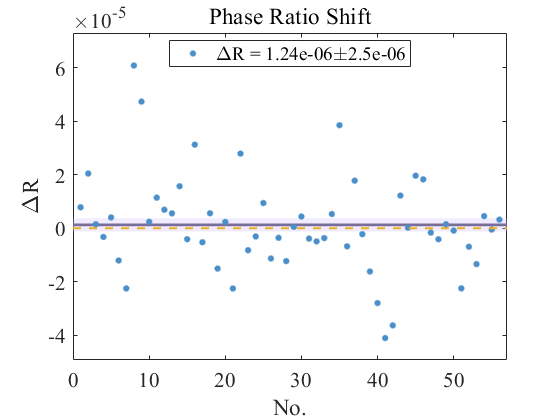


f1 = figure; hold on;

xmin = 0;
xmax = diff_n+1;
ymin = min([-abs(drpm*0.2) min(diff_rp)*0.8 min(diff_rp)*1.2]);
ymax = max([abs(drpm*0.2) max(diff_rp)*0.8 max(diff_rp)*1.2]);

n1 = [1 2 3 4];
patch_list = [0 drpm-drps ; diff_n+1 drpm-drps ; ...
    diff_n+1 drpm+drps ; 0 drpm+drps];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');
l1 = plot([0 xmax],[drpm drpm],Color=[0.48 0.43 0.60],LineWidth=2);

l2 = plot([1:diff_n],diff_rp,'.','MarkerSize',15);
l2.Color = [0.29,0.56,0.79];

l3 = plot([0 xmax],[0 0],'--','LineWidth',1.5,Color=[0.93 0.69 0.13]);

if diff_n < 6
    xticks([]);
end

xlim([xmin xmax]);
ylim([ymin ymax]);

xlabel('No.');
ylabel('\DeltaR');
title('Phase Ratio Shift');
legend('','',['\DeltaR = ',num2str(drpm,'%.2e'),'\pm',num2str(drps,'%.1e')],'',...
    'Location','best');
grid off;
box on;

set(f1,'Visible','on');
set(gca,'FontSize',16,'FontName','Times New Roman');

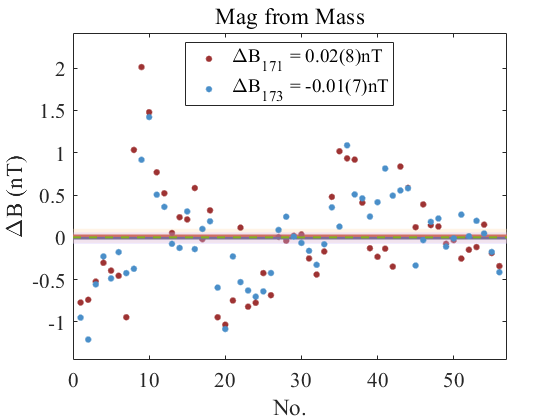


f11 = figure; hold on;
xmin = 0;
xmax = diff_n+1;
ymin = min([-abs([dBm171 dBm173]*0.2) min([dB171,dB173])*0.8 min([dB171,dB173])*1.2]);
ymax = max([abs([dBm171 dBm173]*0.2) max([dB171,dB173])*0.8 max([dB171,dB173])*1.2]);

% 171测得磁场差异 %
n1 = [1 2 3 4];
patch_list = [0 dBm171-dBs171 ; diff_n+1 dBm171-dBs171 ; ...
    diff_n+1 dBm171+dBs171 ; 0 dBm171+dBs171];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[1 0.85 0.67],'EdgeColor','none');
l11 = plot([0 xmax],[dBm171 dBm171],Color=[0.82 0.3 0.12],LineWidth=2);

l12 = plot([1:diff_n],dB171,'.','MarkerSize',15);
l12.Color = [0.62,0.2,0.2];


% 173测得磁场差异 %
n1 = [1 2 3 4];
patch_list = [0 dBm173-dBs173 ; diff_n+1 dBm173-dBs173 ; ...
    diff_n+1 dBm173+dBs173 ; 0 dBm173+dBs173];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');
l21 = plot([0 xmax],[dBm173 dBm173],Color=[0.48 0.43 0.60],LineWidth=2);

l22 = plot([1:diff_n],dB173,'.','MarkerSize',15);
l22.Color = [0.29,0.56,0.79];

l3 = plot([0 xmax],[0 0],'LineStyle','--','LineWidth',1.5,Color=[0.5 0.69 0.13]);


if diff_n < 6
    xticks([]);
end

xlim([xmin xmax]);
ylim([ymin ymax]);

xlabel('No.');
ylabel('\DeltaB (nT)');
title('Mag from Mass');
legend('','',['\DeltaB_{171} = ',num2str(dBm171,'%.2f'),'(',num2str(dBs171*1e2,'%.0f'),')nT'],...
    '','',['\DeltaB_{173} = ',num2str(dBm173,'%.2f'),'(',num2str(dBs173*1e2,'%.0f'),')nT'],'',...
    'Location','best');
grid off;
box on;

set(f11,'Visible','on');
set(gca,'FontSize',16,'FontName','Times New Roman');

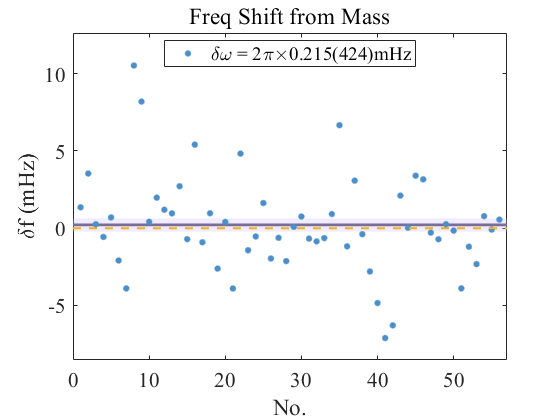


f2 = figure; hold on;

xmin = 0;
xmax = diff_n+1;
ymin = min([-abs(dfm*0.2) min(df)*0.8 min(df)*1.2]);
ymax = max([abs(dfm*0.2) max(df)*0.8 max(df)*1.2]);

n1 = [1 2 3 4];
patch_list = [0 dfm-dfs ; diff_n+1 dfm-dfs ; diff_n+1 dfm+dfs ; 0 dfm+dfs];
patch('Faces',n1,'Vertices',patch_list,...
    'FaceAlpha',0.3,'FaceColor',[0.82 0.74 1],'EdgeColor','none');
l1 = plot([0 xmax],[dfm dfm],Color=[0.48 0.43 0.60],LineWidth=2);

l2 = plot([1:diff_n],df,'.','MarkerSize',15);
l2.Color = [0.29,0.56,0.79];

l3 = plot([0 xmax],[0 0],'--','LineWidth',1.5,Color=[0.93 0.69 0.13]);

if diff_n < 6
    xticks([]);
end

xlim([xmin xmax]);
ylim([ymin ymax]);

xlabel('No.');
ylabel('\deltaf (mHz)');
title('Freq Shift from Mass');
legend('','',['\delta\omega = 2\pi\times',num2str(dfm,'%.3f'),'(',num2str(dfs*1e3,'%.0f'),')mHz'],'',...
    'Location','best');
grid off;
box on;

set(f2,'Visible','on');
set(gca,'FontSize',16,'FontName','Times New Roman');


if save_data == 1
    savefig(f1,[main_dir_0,'dRp.fig']);
    saveas(f1,[main_dir_0,'dRp.png']);
    savefig(f11,[main_dir_0,'dB.fig']);
    saveas(f11,[main_dir_0,'dB.png']);
    % savefig(f12,[main_dir_0,'co_dB.fig']);
    % saveas(f12,[main_dir_0,'co_dB.png']);
    savefig(f2,[main_dir_0,'df.fig']);
    saveas(f2,[main_dir_0,'df.png']);

    save([main_dir_0,'diffR.mat']);
end

